# TP #09 - Ejercicio 10

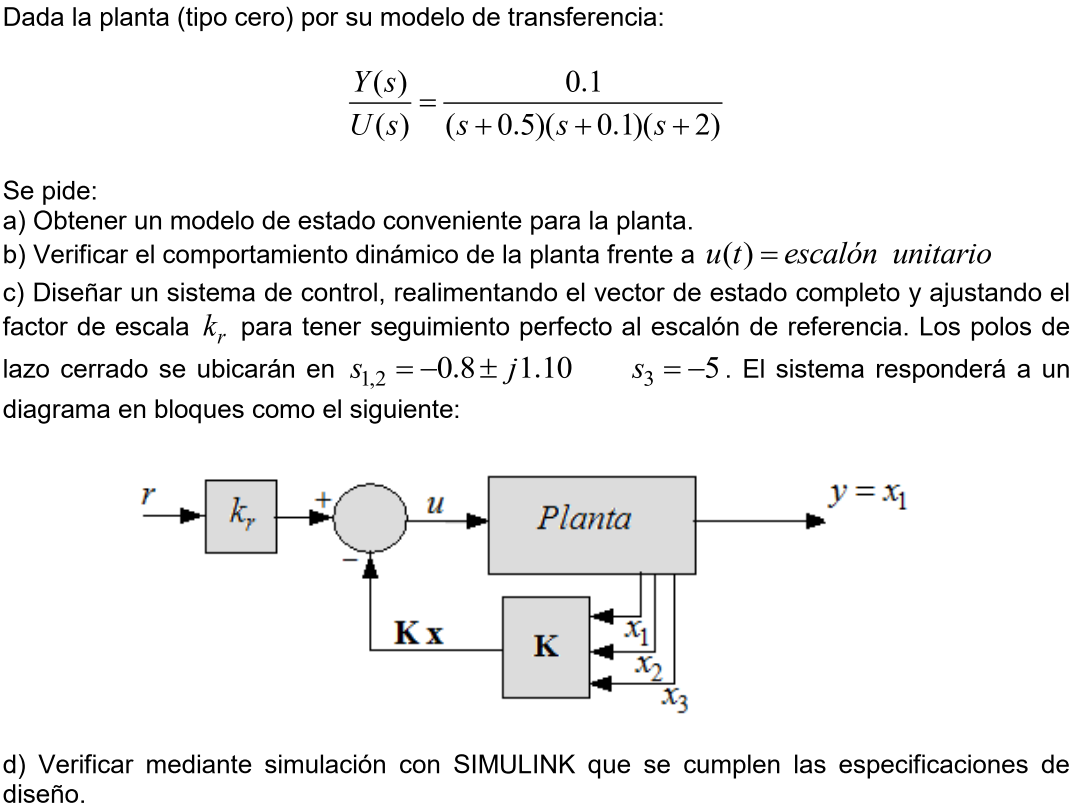

Del enunciado


$$\begin{array}{l}
G\left(s\right)=\frac{1}{\left(s+0\ldotp 5\right)\;\left(s+0\ldotp 1\right)\left(s+2\right)\;}\\
G\left(s\right)=\frac{1}{\left(s^2 +s\;0\ldotp 6+0\ldotp 05\right)\left(s+2\right)}\\
G\left(s\right)\;=\frac{1}{s^3 +s^2 \;2\ldotp 6+s\;1\ldotp 25+0\ldotp 1}
\end{array}$$


En base al modelo canónico controlable podemos definir,


$$\left\lbrack A\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-a_0  & {-a}_1  & {-a}_2 
\end{array}\right\rbrack$$



$$\left\lbrack A\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-0\ldotp 1 & -1\ldotp 25 & -2\ldotp 6
\end{array}\right\rbrack$$



$$\left\lbrack B\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$



$$\left\lbrack C\right\rbrack =\left\lbrack \begin{array}{ccc}
\left(b_0 -b_3 a_0 \right) & \left(b_1 -b_3 a_1 \right) & \left(b_2 -b_3 a_2 \right)
\end{array}\right\rbrack$$



$$\left\lbrack C\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack$$



$$\left\lbrack D\right\rbrack =\left\lbrack b_3 \right\rbrack$$



$$\left\lbrack D\right\rbrack =\left\lbrack 0\right\rbrack$$


Del gráfico tenemos,


$$\begin{array}{l}
\mu \left(t\right)=r\left(t\right)k_r -K\;X\left(t\right)\\
\overset{\ldotp }{X} \left(t\right)=A\;X\left(t\right)+B\mu \left(t\right)\\
\overset{\ldotp }{X} \left(t\right)=A\;X\left(t\right)+B\left(r\left(t\right)k_r -K\;X\left(t\right)\right)\\
\overset{\ldotp }{X} \left(t\right)=\left(A-B\;K\right)X\left(t\right)+B\;r\left(t\right)k_r \;;\left(\mathit{\mathbf{a}}\right)
\end{array}$$


Se pide,


$$\begin{array}{l}
\textrm{PLC}:\;\left(s+0\ldotp 8+\textrm{j1}\ldotp 1\right)\;\left(s+0\ldotp 8-\textrm{j1}\ldotp 1\right)\;\left(s+5\right)\;\\
\textrm{PLC}:\;\left(s^2 +4s+20\right)\left(s+10\right)\\
{\textrm{PLC}:\;s}^3 +s^2 \;6\ldotp 6+s\;9\ldotp 85+9\ldotp 25;\left(\mathit{\mathbf{b}}\right)
\end{array}$$


Quedando entonces,


$$\begin{array}{l}
A-\textrm{BK}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-0\ldotp 1 & -1\ldotp 25 & -2\ldotp 6
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
k_1  & k_2  & k_3 
\end{array}\right\rbrack \\
A-\textrm{BK}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-0\ldotp 1 & -1\ldotp 25 & -2\ldotp 6
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
k_1  & k_2  & k_3 
\end{array}\right\rbrack \\
A-\textrm{BK}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-0\ldotp 1-k_1  & -1\ldotp 25-k_2  & -2\ldotp 6{-k}_3 
\end{array}\right\rbrack 
\end{array}$$


Finalmente hallamos la expresión de los polos deseados,


$$\begin{array}{l}
\left(\textrm{sI}-A+\textrm{BK}\right)=\left\lbrack \begin{array}{ccc}
s & 0 & 0\\
0 & s & 0\\
0 & 0 & s
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-0\ldotp 1-k_1  & -1\ldotp 25-k_2  & -2\ldotp 6{-k}_3 
\end{array}\right\rbrack \\
\left(\textrm{sI}-A+\textrm{BK}\right)=\left\lbrack \begin{array}{ccc}
s & -1 & 0\\
0 & s & -1\\
0\ldotp 1+k_1  & 1\ldotp 25+k_2  & s+2\ldotp 6+k_3 
\end{array}\right\rbrack 
\end{array}$$


Hallamos ahora el determinante,


$$\textrm{det}\left(\textrm{sI}-A+\textrm{BK}\right)=s^3 +s^2 \;\left(2\ldotp 6+k_3 \right)+s\;\left(1\ldotp 25+k_2 \right)+k_1 +0\ldotp 1$$


Reemplazando con lo hallado en **(b)**

- 
$$k_1 =9\ldotp 15$$


- 
$$k_2 =8\ldotp 6$$


- 
$$k_3 =4$$


Podemos además corroborar con la función 'acker'

A = [0 1 0; 0 0 1; -0.1 -1.25 -2.6];
B = [0; 0; 1];
C = [0.1 0 0];
D = [];
PLC=[-0.8+1.1i -0.8-1.1i -5];
disp('Ganancias calculadas con Ackerman:')

Ganancias calculadas con Ackerman:


K=acker(A,B,PLC)

K =     9.1500    8.6000    4.0000


disp('Vector de Realimentción de Estados ([An]):')

Vector de Realimentción de Estados ([An]):


An=A-B*K

An =          0    1.0000         0
         0         0    1.0000
   -9.2500   -9.8500   -6.6000


disp('Posición diseñada de los polos a lazo cerrado:')

Posición diseñada de los polos a lazo cerrado:


PLC_d=eig(An)

PLC_d =   -5.0000 + 0.0000i
  -0.8000 + 1.1000i
  -0.8000 - 1.1000i


Finalmente hallamos el valor de $k_r$, partiendo de **(a)**,


$$\overset{\ldotp }{X} \left(t\right)=\left(A-B\;K\right)X\left(t\right)+B\;r\left(t\right)k_r$$


Aplicamos transformada de Laplace, y con condiciones iniciales nulas


$$\textrm{sX}\left(s\right)-X\left(0\right)=\left(A-B\;K\right)X\left(s\right)+B\;R\left(s\right)k_r$$



$$\textrm{sX}\left(s\right)-\left(A-B\;K\right)X\left(s\right)=B\;R\left(s\right)k_r$$



$$\left(\textrm{sI}-A+B\;K\right)X\left(s\right)=B\;R\left(s\right)k_r$$



$$X\left(s\right)={\left(\mathrm{sI}-A+B\;K\right)}^{-1} B\;R\left(s\right)k_r$$


Tomando la ecuación de la salida,


$$Y\left(s\right)\;=\;C\;X\left(s\right)$$



$$Y\left(s\right)={C\left(\textrm{sI}-A+B\;K\right)}^{-1} B\;R\left(s\right)k_r$$


Como vamos a excitar al sistema con una señal escalón, podemos analizar el teorema de valor final, suponiendo,


$$\lim_{s\to 0} \;s\;Y\left(s\right)\;=1$$



$$\lim_{s\to 0} \;s\;C\;{\left(s\;I-A+B\;K\right)}^{-1} B\;\frac{1}{s}k_r \;=1$$



$$\lim_{s\to 0} \;C\;{\left(s\;I-A+B\;K\right)}^{-1} B\;k_r \;=1$$



$$C\;{\left(-A+B\;K\right)}^{-1} B\;k_r \;=1$$



$$\;k_r \;=\frac{1}{C{\left(-A+B\;K\right)}^{-1} B}$$


Empleando MATLab para evitar el cálculo matricial,

kr = 1/(C*inv(-A+B*K)*B)

kr = 92.5000

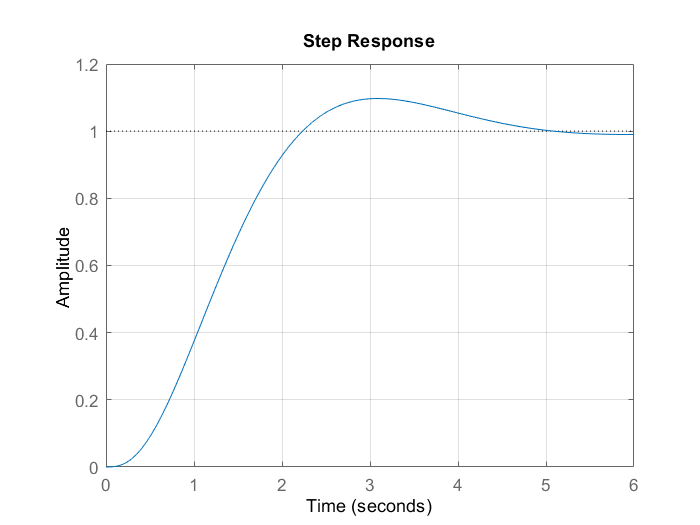

sys=ss(An,B*kr,C,D);
step(sys)
grid on;

Simulink, ejecutar ***TP09_ej10.slx.***